# MATH 3620 Numerical Analysis

# Homework 2

# 07 Feb 2021

close all; clear all ; clc

## `Q1. Analysis of convergence of Composite Trapezoidal Quadrature Rule`

## `1a `

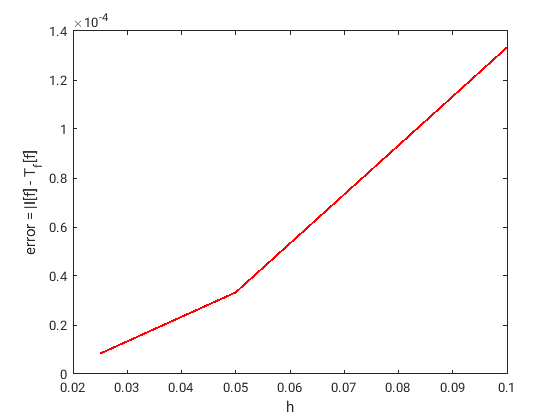

f = @(x) 1./(1 + x.^2);
a = 0;
b = 2;

hlist = [2/20 2/40 2/80];
error = zeros(size(hlist));
T = zeros(size(hlist));
I = atan(b) - atan(a); % exact integral

for i = 1:length(hlist)
    h = hlist(i);
    T(i) = CompositeTrapezoidal(f, a, b, h);
    error(i) = abs(I - T(i));
end

% plot error trend
plot(hlist, error, 'r-', 'LineWidth', 1.5)
xlabel('h')
ylabel('error = |I[f] - T_f[f]')

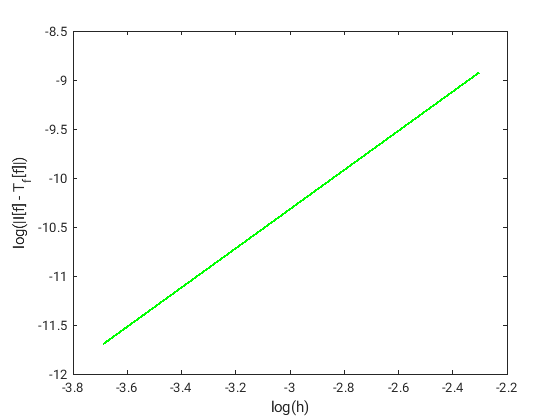

% show error is proportional to h squared
plot(log(hlist), log(error), 'g-', 'LineWidth', 1.5)
xlabel('log(h)')
ylabel('log(|I[f] - T_f[f]|)')

`The log-log plot of the error vs. h is shown above. We can see that ``the slope of the above line is approximately 2. Hence, the CTR has the expected quadratic rate of convergence.`

% compute q(h) from (2.36) in notes
% q(h) should be approximately 4
qh = (T(2) - T(1))/(T(3) - T(2))

qh = 3.9991

`We can see that q(h) is approximately 4 as expected.`

## `1b `

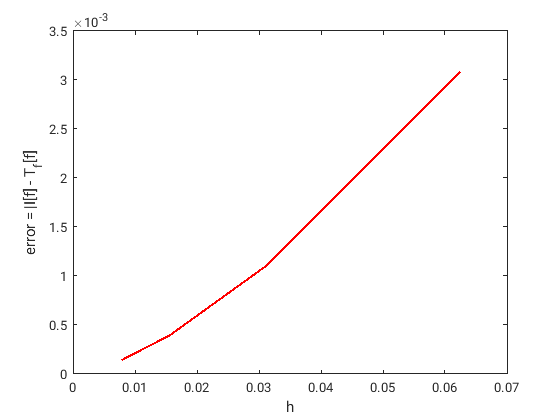

f = @(x) sqrt(x);
a = 0;
b = 1;
Nlist = [16 32 64 128];

hlist = (b - a)./Nlist;
error = zeros(size(hlist));
T = zeros(size(hlist));
I = (2/3)*(b^(3/2) - a^(3/2)); % exact integral

for i = 1:length(hlist)
    h = hlist(i);
    T(i) = CompositeTrapezoidal(f, a, b, h);
    error(i) = abs(I - T(i));
end

% plot error trend
plot(hlist, error, 'r-', 'LineWidth', 1.5)
xlabel('h')
ylabel('error = |I[f] - T_f[f]')

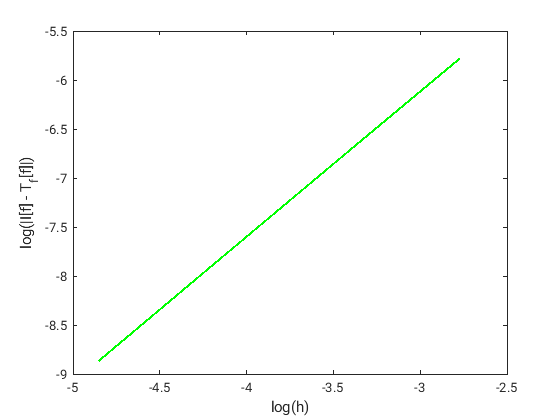


% show error is proportional to h squared
plot(log(hlist), log(error), 'g-', 'LineWidth', 1.5)
xlabel('log(h)')
ylabel('log(|I[f] - T_f[f]|)')

% compute q(h) from (2.36) in notes
% q(h) should be approximately 4
qh = (T(2) - T(1))/(T(3) - T(2))

qh = 2.7782

qh = (T(3) - T(2))/(T(4) - T(3))

qh = 2.7934

`We can see that q(h) is NOT approximately four. And the slope of the log-log plot of error vs. h is less than 2 as well. ``The expected quadratic rate of convergence is not present, because the function f = sqrt(x) is not differentiable at the left end-point of the interval [0, 1]. Hence, our error analysis does not apply.`` If we change the interval to say [1, 2], we get q(h) close to 4 as expected, because the function has a derivative defined all over the interval [1, 2].`

## `Q2. Computing the definite integral of cos(x^2)`

## `2a`

f = @(x) cos(x.^2);
a = 0;
b = sqrt(pi/2);

h = (b-a)/2;
Th = 0;
Thby2 = 0;
Thby4 = 0;

q = (Thby2 - Th)/(Thby4 - Thby2);
tol = 1e-3; % tolerance

while(true)
    Th = CompositeTrapezoidal(f, a, b, h);
    Thby2 = CompositeTrapezoidal(f, a, b, h/2);
    Thby4 = CompositeTrapezoidal(f, a, b, h/4);
    q = (Thby2 - Th)/(Thby4 - Thby2);
    if abs(q - 4) > tol
        h = h/2;
    else
        break
    end
end

fprintf('Approximate value of integral is %1.16g.\n.', Th)

Approximate value of integral is 0.9771309461901362.
.

fprintf('The maximal value of h for which q(h) is approximately 4 equals %f.\n', h)

The maximal value of h for which q(h) is approximately 4 equals 0.039166.


## `2b`

`From (2.25) and (2.26) in the notes, the approximate error is`


$$E \approx -\frac{h^2}{12}\left( f'(\sqrt{\pi/2} - f'(0) \right)$$


`Now,`


$$f'(x) = -2xsin(x^2)$$


`Thus,`

E = -((h^2)/12)*(-2*b*sin(b^2) + 2*a*sin(a^2));
fprintf('Approximate error, E = %1.16g.\n', E)

Approximate error, E = 0.0003204266346379072.


`From (2.34)`

E = (4/3)*(Thby2 - Th);
fprintf('Approximate error, E = %1.16g.\n', E)

Approximate error, E = 0.0003204909674464259.


`We note that the two error estimates are quite close.`

## `2c`

`Improved approximation of integral `$S_h[cos(x^2)]$` is given by`

Sh = Th + E;
fprintf('Improved approximation S_h = %1.16g.\n', Sh)

Improved approximation S_h = 0.9774514371575826.


## `2d`

$S_h$ `converges faster to `$I$ `than `$T_h$ `because the error term of `$S_h$ `is`

$\frac{4}{3}\left( R(h/2) - R(h))$ `(2.29, 2.32, 2.37)`

`where `$R(h)$ `is such that`

$\lim_{h \rightarrow 0} \frac{R(h)}{h^2} = 0$ `(2.27)`

`Thus, the error term of `$S_h$ `covnverges faster than `$h^2$ `and hence has a rate of convergence that exceeds the quadratic rate of convergence of `$T_h$`.`

`Also, `$S_h$ `is more accurate` `than `$T_h$ `because the error term of `$S_h$ `is smaller than the error term of `$T_h$`.`

## `Exercise 1`

`We know from (2.23) that `


$$|E_h(f)| \leq \frac{1}{12}(b-a)h^2M_2 $$


`where we can take`


$$M_2 = \max_{x \in [a, b]} |f''(x)|$$


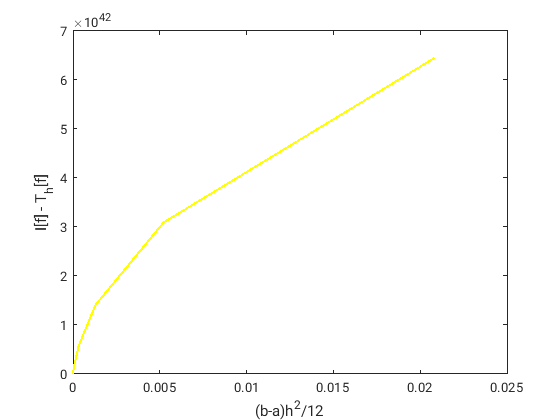

f = @(x) exp(100*x);
a = 0;
b = 1;
h = (b-a)/2;

I = (1/100)*(exp(100*b) - exp(100*a));

E = zeros(1, 10);
C = zeros(1, 10);
for i = 1:10
    Th = CompositeTrapezoidal(f, a, b, h);
    E(i) = abs(I - Th);
    C(i) = (b-a)*h*h/12;
    h = h/2;
end
plot(C, E, 'y-', 'LineWidth', 1.5)
xlabel('(b-a)h^2/12')
ylabel('I[f] - T_h[f]')

% constant M_2 = max|f''|
M_2 = 100*100*exp(100*b);
% check whether max(E/C) < M_2
max(E./C) < M_2

ans = logical
   1


`Thus, we have verified the validity of (2.23). However, the absolute error values have very high magnitudes. Perhaps, a relative error measure would make more sense in this scenario as an error metric. However, the composite trapezoidal rule does not provide us accurate estimates. It is likely due to the highly steep nature of the function, and hence will require a very very small value of 'h' for reasonably accurate estimates.  `

## `Exercise 2`

f = @(x) exp(x);
a = 0;
b = 1;
h = 1/16;

Th = CompositeTrapezoidal(f, a, b, h);
Thby2 = CompositeTrapezoidal(f, a, b, h/2);
Thby4 = CompositeTrapezoidal(f, a, b, h/4);

qh = (Thby2 - Th)/(Thby4 - Thby2)

qh = 3.9998

Th;
fprintf('Approximate Value of Integral = %1.16g.\n', Th);

Approximate Value of Integral = 1.718841128579994.


Sh = Th + (4/3)*(Thby2 - Th);
fprintf('Improved Approximation for Value of Integral = %1.16g.\n', Sh);

Improved Approximation for Value of Integral = 1.718281837561772.


I = exp(b) - exp(a); % exact value of integral
fprintf('Exact Value of Integral = %1.16g.\n', I);

Exact Value of Integral = 1.718281828459046.


`Hence `$T_h$` is accurate to only 3 decimal places whereas `$S_h$` is accurate to 7 decimal places.`

## `Exercise 3`

f = @(x) 1./(2 + sin(x));
a = 0;
b = 2*pi;

L = 1;
N = 2^L;
h = (b - a)/N;
tol = 2^(-50); % machine precision in DP = 2^(-52), higher tolerance causes machine crash

I = 2*pi/sqrt(3);

while (true)
    Th = CompositeTrapezoidal(f, a, b, h);
    if abs(I - Th) < tol
        break
    else
        L = L + 1;
        N = 2^L;
        h = (b - a)/N;
    end
end

fprintf('The minimum value of N required for T_h[f] to reach machine precision in DP is: %1.16g', N)

The minimum value of N required for T_h[f] to reach machine precision in DP is: 32

L = 1;
N = 2^L;
h = (b - a)/N;

while (true)
    Th = CompositeTrapezoidal(f, a, b, h);
    Thby2 = CompositeTrapezoidal(f, a, b, h/2);
    Sh = Th + (4/3)*(Thby2 - Th);
    if abs(I - Sh) < tol
        break
    else
        L = L + 1;
        N = 2^L;
        h = (b - a)/N;
    end
end

fprintf('The minimum value of N required for S_h[f] to reach machine precision in DP is: %1.16g', N)

The minimum value of N required for S_h[f] to reach machine precision in DP is: 32

## `Function that implements Composite Trapezoidal Rule`

function T = CompositeTrapezoidal(funcn, a, b, h)
    % create vector of evaluation points
    x = a:h:b;
    % compute integral of funcn from a to b
    T = h*(sum(funcn(x)) - (funcn(a) + funcn(b))/2); 
end